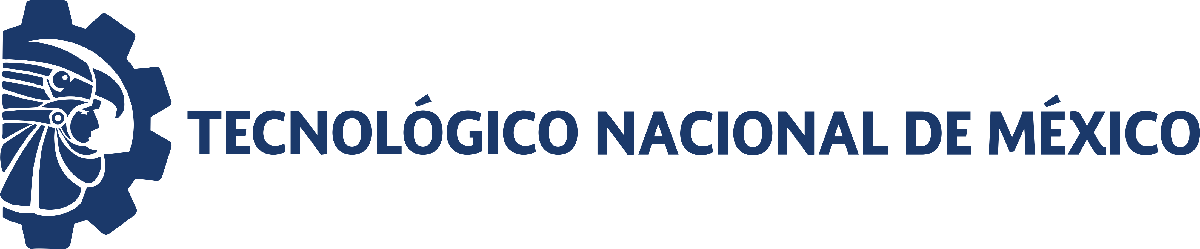                                 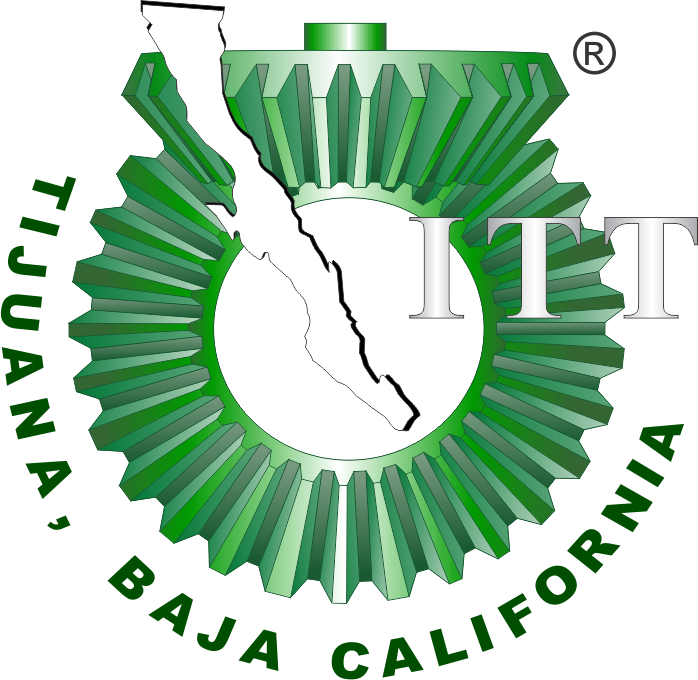

# Práctica 2: Sistema Cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

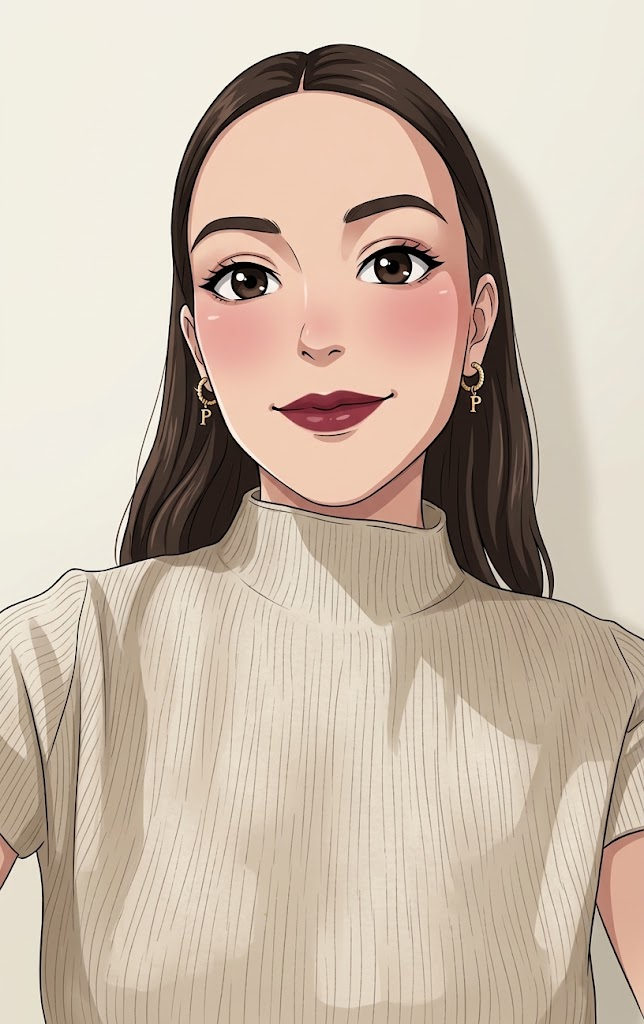

Nombre del alumno: Vanessa Yamileth Suarez Ceja

Número de control: 23212236

Correo institucional: L23212236**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistemaP2')
parameters.StopTime = '15';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('sistemaP2', parameters);

t_data = (0:0.1:15)';
t= (0:0.001:15)';
Pa=interp1(t_data, x.Pa, t, 'previous');

writematrix(Pa, 'signal.xlsx');

## Resultados: Normotenso, Hipotenso, Hipertenso

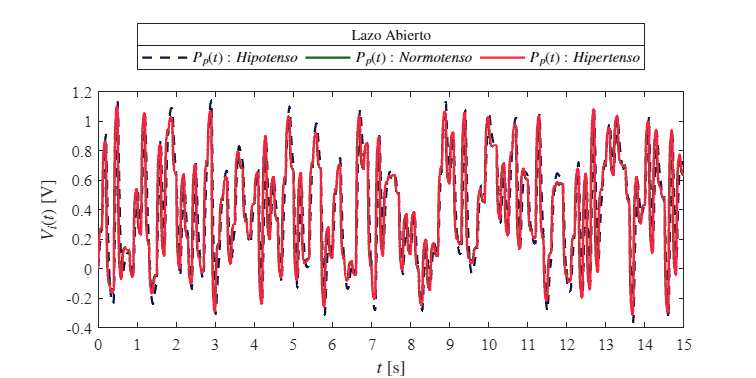

plotsignals(x.t,x.PpL,x.PpN,x.PpH,'Lazo Abierto')

## Resultados: Normotenso, Hipotenso y PID Hipotenso

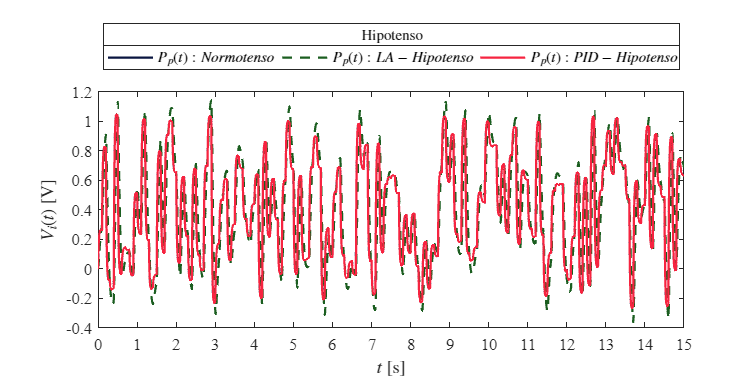

plotsignals1(x.t,x.PpN,x.PpL,x.PIDL,'Hipotenso')

## Resultados: Normotenso, Hipertenso, PID Hipertenso

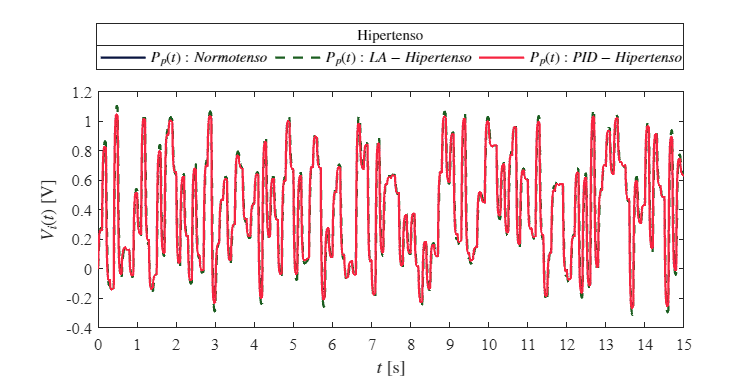

plotsignals2(x.t,x.PpN,x.PpH,x.PIDH, 'Hipertenso')

## **Modelo de EDOs**

par_hipo = [0.010,0.001,1.000,3.500]; %[Z,L,R,C]
par_normo = [0.010,0.001,1.000,1.500];
par_hiper = [0.010,0.001,1.000,1.000]

par_hiper =     0.0100    0.0010    1.0000    1.0000


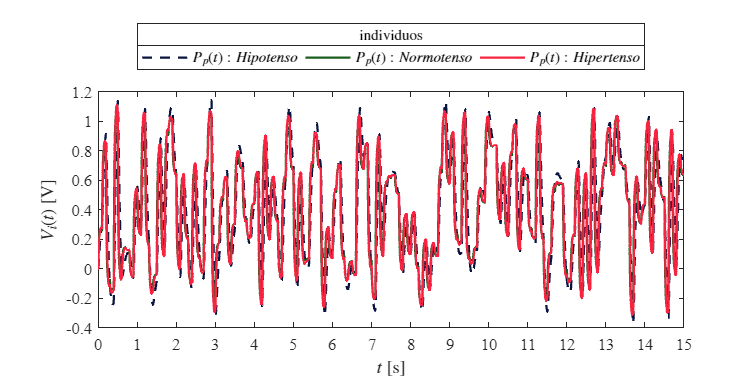

PpN = cardio(par_normo,Pa,t);
PpL = cardio(par_hipo,PpN,t);
PpH = cardio(par_hiper,PpN,t);
plotsignals(t,PpL,PpN,PpH, 'individuos')

function Pp = cardio(par,Pa,t,caso)
    Z= par(1); L= par(2); R= par(3); C= par(4);
    n = round(t(end)/t(2));
    dt = t(2);

    FL = zeros(length(t),1); FL(1) = 0;
    Pp = zeros(length(t),1); Pp(1) = 0;

    for i = 1:n
        FL(i+1) = FL(i) + (-(1/L)*Pp(i) + (1/L)*Pa(i))*dt;
        Pp(i+1) = Pp(i) + ((1/C)*FL(i) - (1/(Z*C) + 1/(R*C))*Pp(i) + 1/(Z*C)*Pa(i))*dt;
    end
end


## **Función: Respuesta de la simulación **

function plotsignals(t,x1,x2,x3,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [9,21,64]/255;
    clr2 = [27,94,32]/255;
    clr3 = [246,36,64]/255;
    order = [clr1;clr2;clr3]; colororder(order)

    plot(t,x1,'--',t,x2,'-',t,x3,'-','lineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));
    
    L = legend('$P_p(t):Hipotenso$','$P_p(t):Normotenso$','$P_p(t):Hipertenso$');
    set(L,'interpreter','latex','location','northoutside','orientation','Horizontal')
    title(L,[signal])

    xlabel('$t$ [s]','Interpreter','latex')
    ylabel('$V_i(t)$ [V]','Interpreter','latex')

    xlim([0 15]); xticks(0:1:15)

    ylim([-0.4 1.2]); yticks(-0.4:0.2:1.2)

    exportgraphics(gcf,[signal,'_matlab.pdf'],'contenttype','vector')
end

function plotsignals1(t,x1,x2,x3,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [9,21,64]/255;
    clr2 = [27,94,32]/255;
    clr3 = [246,36,64]/255;
    order = [clr1;clr2;clr3]; colororder(order)

    plot(t,x1,'-',t,x2,'--',t,x3,'-','lineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));
    
    L = legend('$P_p(t):Normotenso$','$P_p(t):LA-Hipotenso$','$P_p(t):PID-Hipotenso$');
    set(L,'interpreter','latex','location','northoutside','orientation','Horizontal')
    title(L,[signal])

    xlabel('$t$ [s]','Interpreter','latex')
    ylabel('$V_i(t)$ [V]','Interpreter','latex')

    xlim([0 15]); xticks(0:1:15)

    ylim([-0.4 1.2]); yticks(-0.4:0.2:1.2)

    exportgraphics(gcf,[signal,'_matlab.pdf'],'contenttype','vector')
end

function plotsignals2(t,x1,x2,x3,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
   clr1 = [9,21,64]/255;
    clr2 = [27,94,32]/255;
    clr3 = [246,36,64]/255;
    order = [clr1;clr2;clr3]; colororder(order)

    plot(t,x1,'-',t,x2,'--',t,x3,'-','lineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));
    
    L = legend('$P_p(t):Normotenso$','$P_p(t):LA-Hipertenso$','$P_p(t):PID-Hipertenso$');
    set(L,'interpreter','latex','location','northoutside','orientation','Horizontal')
    title(L,[signal])

    xlabel('$t$ [s]','Interpreter','latex')
    ylabel('$V_i(t)$ [V]','Interpreter','latex')

    xlim([0 15]); xticks(0:1:15)

    ylim([-0.4 1.2]); yticks(-0.4:0.2:1.2)

    exportgraphics(gcf,[signal,'_matlab.pdf'],'contenttype','vector')
end
